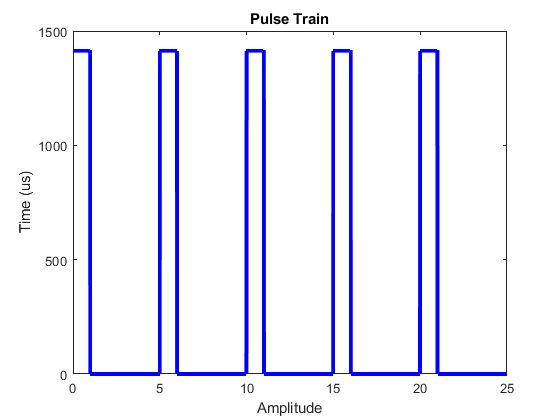

clear all
close all

tau=1e-6;
PRT=5e-6;
fc=5e6;
Pt=1e6;
Losses=70;
N=5;
fs=100e6; %sampling frequency
R=0; %m

dt=1/fs;
Tfinal=N*PRT;
vt=(0:dt:Tfinal-dt); %vector of time
m=length(vt);

%Create the amplitude code
N_tau=round(tau/dt); % how many samples fits in a single pulse
N_PRT=round((PRT-tau)/dt); % how many samples fit during the listening time


%Calculating the amplitude
A=sqrt(2*Pt);
v_A=[A*ones(1,N_tau) zeros(1,N_PRT)]; % creem un vector que tingui molts valors de Amplitud

v_Aall=[]; % definirem en aquest vector el tren de polsos

for i=1:N % creem un bucle per anar afegin vectors un darrere l'altre N cops
    v_Aall=[v_Aall v_A];
end

figure(1)
plot(vt*1e6, v_Aall, 'b', 'Linewidth',3)
hold on
title('Pulse Train')
ylabel('Time (us)')
xlabel ('Amplitude')

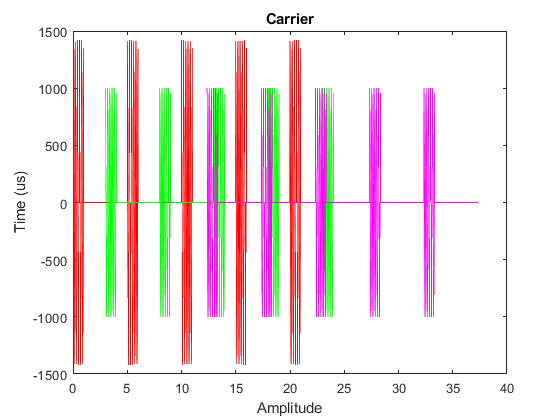



%Modulem la senyal per poder-la enviar
sc=cos(2*pi*fc*vt);

figure(2)
plot(vt*1e6, sc, 'r', 'Linewidth',1)
hold on
title('Carrier')
ylabel('Time (us)')
xlabel ('Amplitude')


sm=sc.*v_Aall; % multipliquem valor per valor els dos vectors

plot(vt*1e6,sm,'r')


R_Target1=450; %m
R_Target2=1852; %m

%calculated delayed times
c=3e8;
T_Target1=2*R_Target1/c;
T_Target2=2*R_Target2/c;


plot ((vt+T_Target1)*1e6,1/sqrt(2)*sm,'g')
plot ((vt+T_Target2)*1e6,1/sqrt(2)*sm,'m')

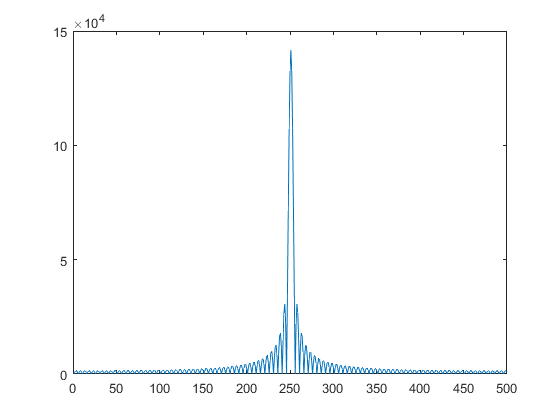





%per saber la distancia des del grafic pots mesurar directament el temps al
%que esta separat i podem aillar Tr1=2*Range1/c (en el cas que la senyal del
%target la rebem abans de poder-la tornar a enviar.

% Si rebem la resposta despres d'haver enviat no tenim la certesa a quina
% de les senyals respon. Per tant Range2=(c*Tr2/2)+ 2* Rmax av --> Rmax av:
% distancia maxima no ambigua = c*PRT/2

%Per solocionar-ho podem espaiar més els polsos, per exemple a 14
%microsegons el PRT


% fem la tau més petita si es solapen els dos echos



%exercici 4

df=1/dt; % vector de frequencies
m=length(vt);
vf=(0:df:m*df-df);

figure (3)
plot(fftshift(abs(fft(v_A)))) 

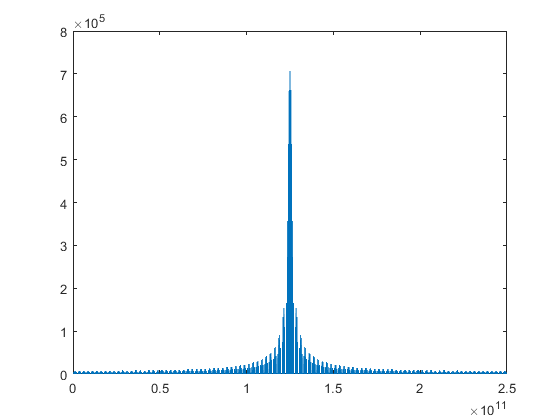

%% la transformada de fourier de un pols rectangular es una sinc, PRT=5e-6s pel que f=1/PRT=



figure (4)
plot(vf,fftshift(abs(fft(v_Aall))))

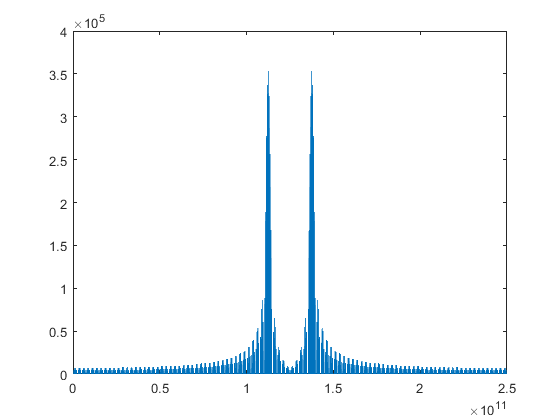


%

figure (5)
plot(vf,fftshift(abs(fft(sm))))


% centrat els dos pics a frequencia portadora fc
% la separació entre dos 'linies' es de PMF
%amplada espectral del pols (AMPLE DEL QUE SERIA EL LÒBUL) = 2/tau

